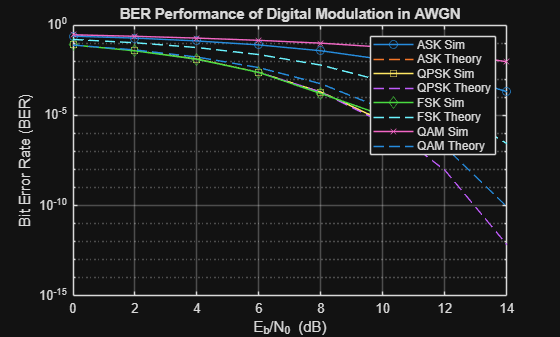

clc;
clear;
close all;

%% ----------------------------------
% PARAMETERS
%% ----------------------------------
N = 1e5;                 % Number of bits
EbN0_dB = 0:2:14;        % SNR range
BER_ASK = zeros(size(EbN0_dB));
BER_QPSK = zeros(size(EbN0_dB));
BER_FSK = zeros(size(EbN0_dB));
BER_QAM = zeros(size(EbN0_dB));

%% ----------------------------------
% LOOP OVER SNR
%% ----------------------------------
for k = 1:length(EbN0_dB)
    
    EbN0 = 10^(EbN0_dB(k)/10);
    noise_var = 1/(2*EbN0);
    
    %% ------------------------------
    % 1. ASK (Binary)
    %% ------------------------------
    bits = randi([0 1], 1, N);
    s = bits; % 0 or 1
    
    noise = sqrt(noise_var)*randn(1,N);
    r = s + noise;
    
    detected = r > 0.5;
    BER_ASK(k) = sum(bits ~= detected)/N;
    
    %% ------------------------------
    % 2. QPSK
    %% ------------------------------
    bits = randi([0 1], 1, 2*N);
    
    b1 = bits(1:2:end);
    b2 = bits(2:2:end);
    
    s = (2*b1-1) + 1j*(2*b2-1); % QPSK symbols
    
    noise = sqrt(noise_var)*(randn(1,N) + 1j*randn(1,N));
    r = s + noise;
    
    detected_b1 = real(r) > 0;
    detected_b2 = imag(r) > 0;
    
    BER_QPSK(k) = (sum(b1 ~= detected_b1) + sum(b2 ~= detected_b2)) / (2*N);
    
    %% ------------------------------
    % 3. FSK (Coherent BFSK)
    %% ------------------------------
    bits = randi([0 1], 1, N);
    
    s = 2*bits - 1; % orthogonal approx
    
    noise = sqrt(noise_var)*randn(1,N);
    r = s + noise;
    
    detected = r > 0;
    BER_FSK(k) = sum(bits ~= detected)/N;
    
    %% ------------------------------
    % 4. 16-QAM
    %% ------------------------------
    M = 16;
    kq = log2(M);
    
    bits = randi([0 1], 1, N*kq);
    
    symbols = bi2de(reshape(bits, kq, []).', 'left-msb');
    s = qammod(symbols, M, 'UnitAveragePower', true);
    
    noise = sqrt(noise_var)*(randn(size(s)) + 1j*randn(size(s)));
    r = s + noise;
    
    detected_symbols = qamdemod(r, M, 'UnitAveragePower', true);
    detected_bits = de2bi(detected_symbols, kq, 'left-msb').';
    detected_bits = detected_bits(:).';
    
    BER_QAM(k) = sum(bits ~= detected_bits)/length(bits);
end

%% ----------------------------------
% THEORETICAL BER
%% ----------------------------------
EbN0_lin = 10.^(EbN0_dB/10);

BER_ASK_th = 0.5*erfc(sqrt(EbN0_lin/2));
BER_QPSK_th = 0.5*erfc(sqrt(EbN0_lin));
BER_FSK_th = 0.5*erfc(sqrt(EbN0_lin/2));
BER_QAM_th = (3/8)*erfc(sqrt((4/5)*EbN0_lin)); % approx 16-QAM

%% ----------------------------------
% PLOT RESULTS
%% ----------------------------------
figure;
semilogy(EbN0_dB, BER_ASK, 'o-', EbN0_dB, BER_ASK_th, '--');
hold on;
semilogy(EbN0_dB, BER_QPSK, 's-', EbN0_dB, BER_QPSK_th, '--');
semilogy(EbN0_dB, BER_FSK, 'd-', EbN0_dB, BER_FSK_th, '--');
semilogy(EbN0_dB, BER_QAM, 'x-', EbN0_dB, BER_QAM_th, '--');

legend('ASK Sim','ASK Theory','QPSK Sim','QPSK Theory',...
       'FSK Sim','FSK Theory','QAM Sim','QAM Theory');

xlabel('E_b/N_0 (dB)');
ylabel('Bit Error Rate (BER)');
title('BER Performance of Digital Modulation in AWGN');
grid on;